## EXPERIENCING WITH REAL-TIME SNAPSHOT

clear camera

% Load trained model
disp("Loaded 3 trained models for experiencing.")

Loaded 3 trained models for experiencing.


[model1, model2, model3] = load_trained_models();

model1_name = "resnet50_transferednet"

model2_name = "resnet18_transferednet"

model3_name = "resnet18_transferednet_with_noise"

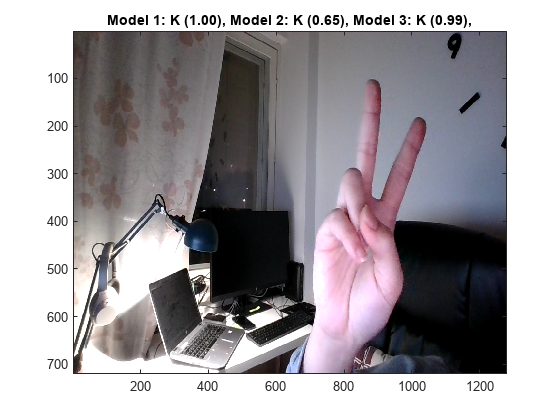


% Experience classification performance with one-time snapshot
camera = webcam;

% figure;
% im = snapshot(camera);
% image(im)
% im = imresize(im,inputSize(1:2));
% [label,score] = classify(netTransfer,im);
% title({char(label),num2str(max(score),2)});
% drawnow;

% Experience continously real-time classification performance if there
% exists at least a camera
h = figure;
while ishandle(h)
    im = snapshot(camera);
    image(im)
    im = imresize(im,model1.inputSize(1:2));
    [label1,score1] = classify(model1.netTransfer,im);
    [label2,score2] = classify(model2.netTransfer,im);
    [label3,score3] = classify(model3.netTransfer,im);
%     title('Predicted classes from 3 trained models')
    title(sprintf("Model 1: %s (%0.2f), Model 2: %s (%0.2f), Model 3: %s (%0.2f),", string(label1), max(score1), string(label2), max(score2), string(label3), max(score3)));
    drawnow;
end


clear camera

function [model1, model2, model3] = load_trained_models()
    model1_name = "resnet50_transferednet"
    model2_name = "resnet18_transferednet"
    model3_name = "resnet18_transferednet_with_noise"
    
    path_to_trained_model1 = sprintf("services\\%s.mat", model1_name);
    path_to_trained_model2 = sprintf("services\\%s.mat", model2_name);
    path_to_trained_model3 = sprintf("services\\%s.mat", model3_name);
    
    load(path_to_trained_model1, 'netTransfer', 'inputSize');
    load(path_to_trained_model2, 'netTransfer', 'inputSize');
    load(path_to_trained_model3, 'netTransfer', 'inputSize');
    
    model1_vars = {'netTransfer', 'inputSize'};
    model2_vars = {'netTransfer', 'inputSize'};
    model3_vars = {'netTransfer', 'inputSize'};
    
    model1 = load(path_to_trained_model1,model1_vars{:});
    model2 = load(path_to_trained_model2,model2_vars{:});
    model3 = load(path_to_trained_model3,model3_vars{:});
end